# Polinomios de interpolación en el análisis de temperatura

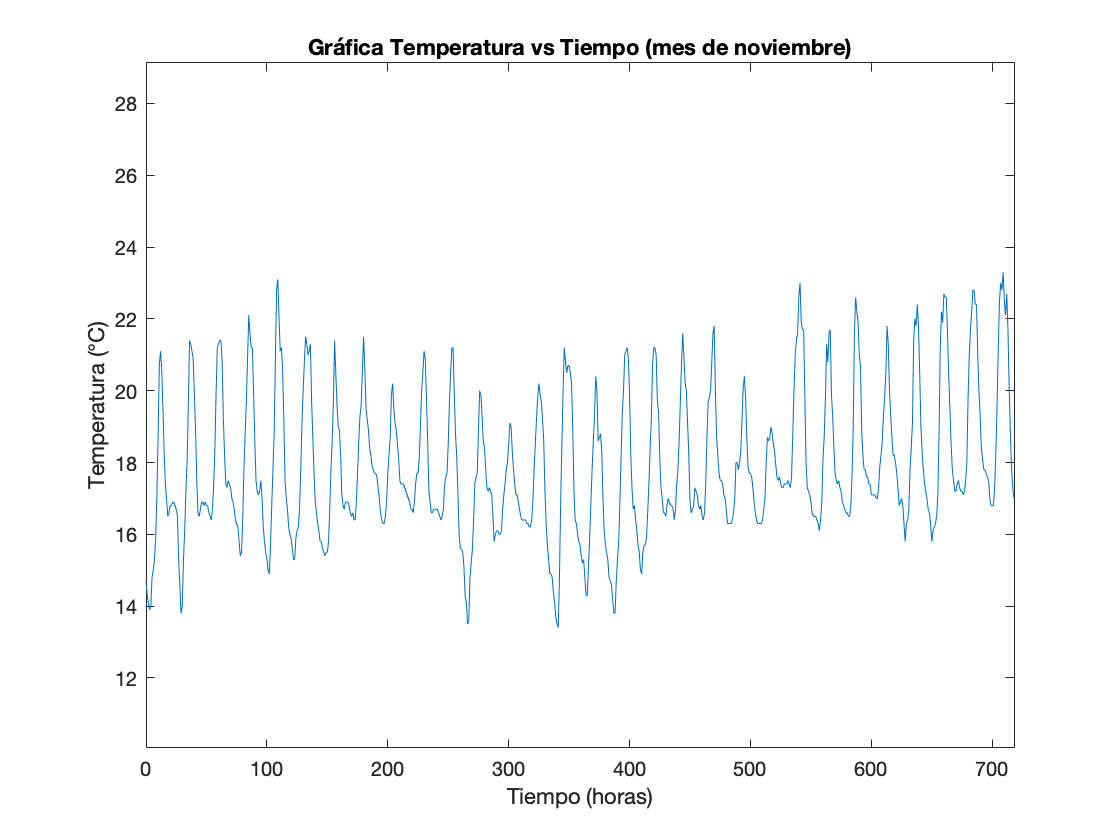

T = CargarData('data.csv');
t = (0:1:length(T)-1);

GraficaGeneral(T, t); hold off;

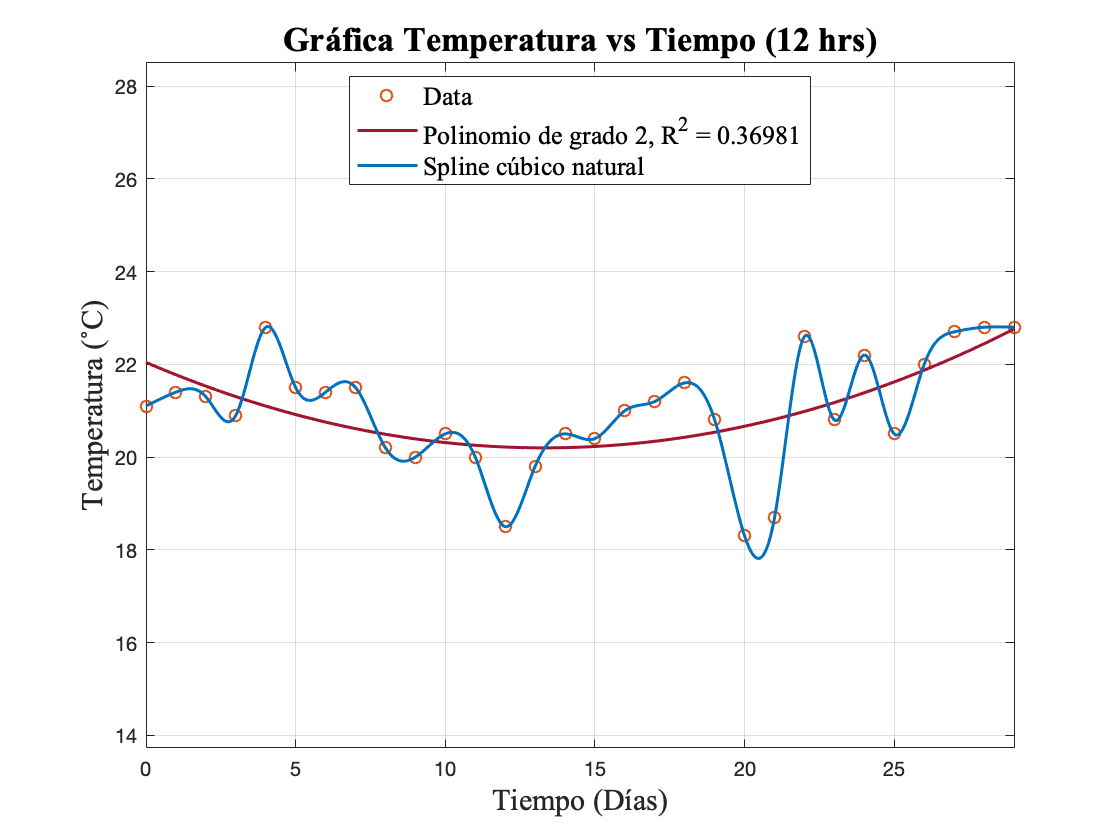

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12; % Se define por defecto el mediodía
    grado = 9; % Se define por defecto un polinomio de mínimos cuadrados de grado 3
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end
[t, T, ~, ~] = GraficaSpline(T, hora+1, grado); 
hold off

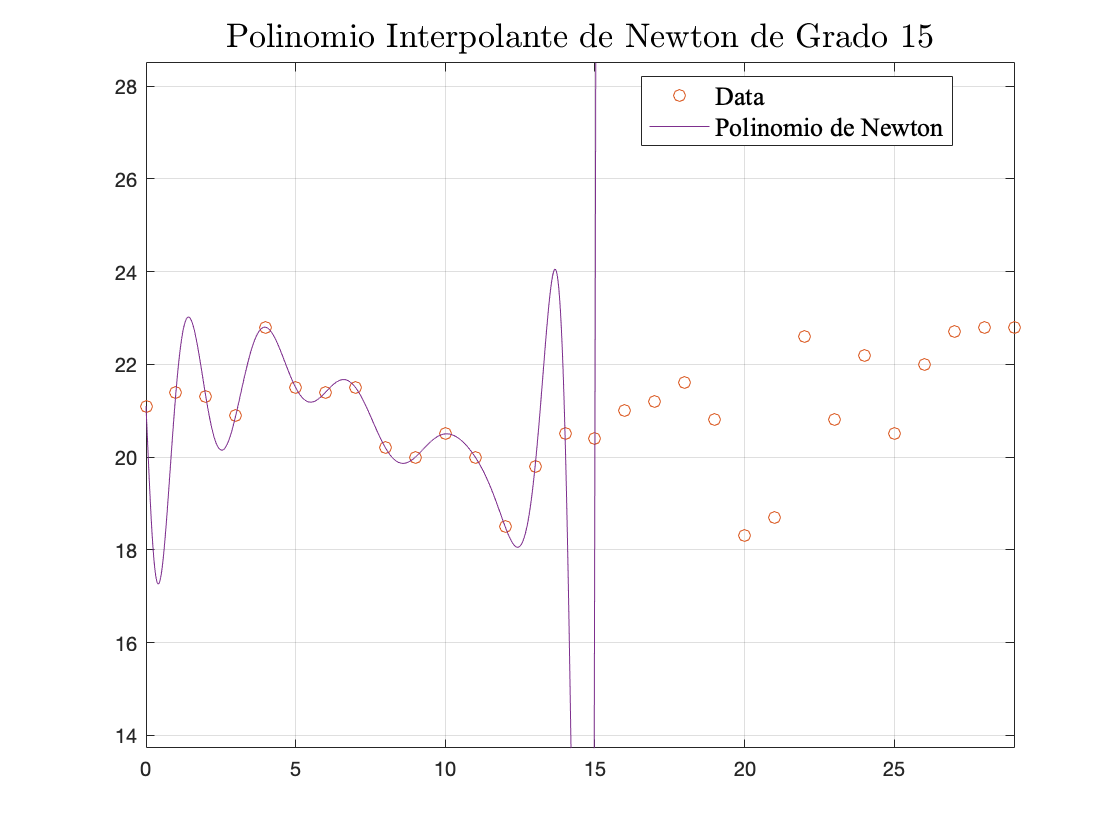

GraficaNewton(t, T, length(t)/2)